clear all; close all; clc;

%%%%data x1--Snowshoe Hare   x2----Canada Lynx
x1 = [20,20,52,83,64,68,83,12,36,150,110,60,7,10,70,...
    100,92,70,10,11,137,137,18,22,52,83,18,10,9,65];
x2 = [32,50,12,10,13,36,15,12,6,6,65,70,40,9,20,...
    34,45,40,15,15,60,80,26,18,37,50,35,12,12,25];

slices = 30;
t = linspace(0,58,slices);
dt = t(2) - t(1);
X =[x1;x2];
X1 = X(:,1:end-1);
X2 = X(:,2:end);
r = 2;

## Q1: basic DMD model

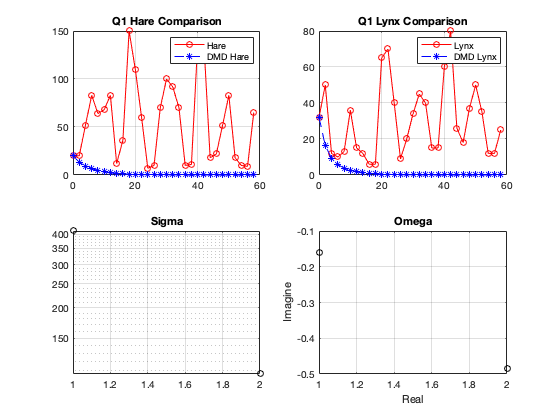


[Phi_q1,omega_q1,lambda_q1,b_q1,Xdmd_q1,S_q1] = DMD2(X1,X2,r,t);

fq1 = figure;
subplot(2,2,1)
plot(t,x1,'ro-',t,abs(Xdmd_q1(1,:)),'b*--')
legend('Hare','DMD Hare');
title('Q1 Hare Comparison')
grid on

subplot(2,2,2)
plot(t,x2,'ro-',t,abs(Xdmd_q1(2,:)),'b*--')
legend('Lynx','DMD Lynx');
title('Q1 Lynx Comparison')
grid on

subplot(2,2,3);
semilogy(abs(diag(S_q1)),'ko');
title('Sigma')
grid on

subplot(2,2,4)
plot(omega_q1,'ko')
title('Omega')
xlabel('Real')
ylabel('Imagine')
grid on

%semilogy(diag(S),'ko')

## Q2: time-delay DMD

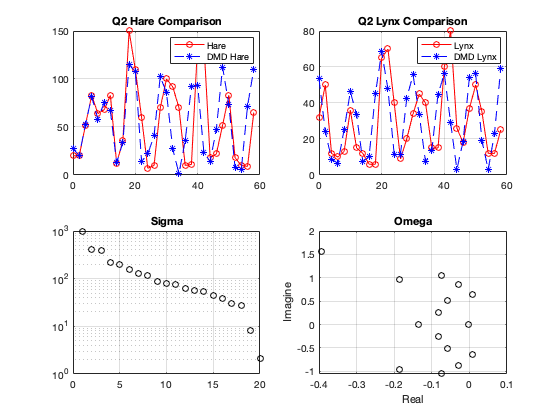

X1_q2 =[];
X2_q2 =[];
kk = 10;
for j=1:kk
    X1_q2 = [X1_q2;x1(j:29-kk+j);x2(j:29-kk+j)];
    X2_q2 = [X2_q2;x1(j+1:29-kk+j+1);x2(j+1:29-kk+j+1)];
    
end
r_q2 = 15;

[Phi_q2,omega_q2,lambda_q2,b_q2,Xdmd_q2,S_q2] = DMD2(X1_q2,X2_q2,r_q2,t);

fq2 = figure;
subplot(2,2,1)
plot(t,x1,'ro-',t,abs(Xdmd_q2(1,:)),'b*--')
legend('Hare','DMD Hare');
title('Q2 Hare Comparison')
grid on

subplot(2,2,2)
plot(t,x2,'ro-',t,abs(Xdmd_q2(2,:)),'b*--')
legend('Lynx','DMD Lynx');
title('Q2 Lynx Comparison')
grid on

subplot(2,2,3);
semilogy(abs(diag(S_q2)),'ko');
title('Sigma')
grid on

subplot(2,2,4)
plot(omega_q2,'ko')
title('Omega')
xlabel('Real')
ylabel('Imagine')
grid on

## Q3: Koopman, consider Empirical Predator-Prey models

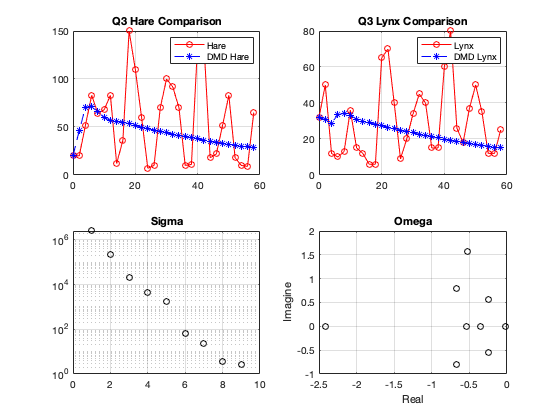

X_q3 = [x1;x2;x1.*x2;x1.*x1;x2.*x2;x1.*x1.*x2;x1.*x2.*x2;x1./x2;x2./x1];
X1_q3 = X_q3(:,1:end-1);
X2_q3 = X_q3(:,2:end);

r_q3 = 9;

[Phi_q3,omega_q3,lambda_q3,b_q3,Xdmd_q3,S_q3] = DMD2(X1_q3,X2_q3,r_q3,t);

fq3 = figure;
subplot(2,2,1)
plot(t,x1,'ro-',t,abs(Xdmd_q3(1,:)),'b*--')
legend('Hare','DMD Hare');
title('Q3 Hare Comparison')
grid on

subplot(2,2,2)
plot(t,x2,'ro-',t,abs(Xdmd_q3(2,:)),'b*--')
legend('Lynx','DMD Lynx');
title('Q3 Lynx Comparison')
grid on

subplot(2,2,3);
semilogy(abs(diag(S_q3)),'ko');
title('Sigma')
grid on

subplot(2,2,4)
plot(omega_q3,'ko')
title('Omega')
xlabel('Real')
ylabel('Imagine')
grid on

## Q4: Best fit nonlinear dynamic system model

%%% Step 1, try to combine time-delay and  Koopman
% X1_q4 =[];
% X2_q4 =[];
% kk = 10;
% for j=1:kk
%     %X1_q4 = [X1_q4;x1(j:29-kk+j);x2(j:29-kk+j);x1(j:29-kk+j).*x2(j:29-kk+j)];
%    % X2_q4 = [X2_q4;x1(j+1:29-kk+j+1);x2(j+1:29-kk+j+1);x1(j+1:29-kk+j+1).*x2(j+1:29-kk+j+1)];
%    
%    X1_q4 = [X1_q4;x1(j:29-kk+j);x2(j:29-kk+j);x1(j:29-kk+j).*x2(j:29-kk+j);x1(j:29-kk+j).*x1(j:29-kk+j).*x2(j:29-kk+j)];
%    X2_q4 = [X2_q4;x1(j+1:29-kk+j+1);x2(j+1:29-kk+j+1);x1(j+1:29-kk+j+1).*x2(j+1:29-kk+j+1);x1(j+1:29-kk+j+1).*x1(j+1:29-kk+j+1).*x2(j+1:29-kk+j+1)];
%    
% end
% 
% r_q4 = 20;
% 
% [Phi_q4,omega_q4,lambda_q4,b_q4,Xdmd_q4,S_q4] = DMD2(X1_q4,X2_q4,r_q4,t);
% 
% fq4 = figure;
% subplot(2,2,1)
% plot(t,x1,'ro-',t,abs(Xdmd_q4(1,:)),'b*--')
% legend('Hare','DMD Hare');
% title('Q4 Hare Comparison')
% grid on
% 
% subplot(2,2,2)
% plot(t,x2,'ro-',t,abs(Xdmd_q4(2,:)),'b*--')
% legend('Lynx','DMD Lynx');
% title('Q4 Lynx Comparison')
% grid on
% 
% subplot(2,2,3);
% semilogy(abs(diag(S_q4)),'ko');
% title('Sigma')
% grid on
% 
% subplot(2,2,4)
% plot(omega_q4,'ko')
% title('Omega')
% xlabel('Real')
% ylabel('Imagine')
% grid on
% 
x1_q4 = x1.';
x2_q4 = x2.';

A1 = [x1_q4,x2_q4,x1_q4.*x2_q4,x1_q4.*x1_q4.*x2_q4,x1_q4.*x2_q4.*x2_q4,x1_q4.*x1_q4,x2_q4.*x2_q4];
%A1 = [x1_q4.*x2_q4,x1_q4.*x1_q4.*x2_q4,x1_q4.*x2_q4.*x2_q4,x1_q4.*x1_q4,x2_q4.*x2_q4];

%xi1 = pinv(A1)*x1_q4;
%xi2 = pinv(A1)*x2_q4;

xi1 = A1\x1_q4;
xi2 = A1\x2_q4;

%xi1 = lasso(A1,x1_q4,'Lambda',0.5);
%xi2 = lasso(A1,x2_q4,'Lambda',0.5);

fq4_1 = figure()

fq4_1 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


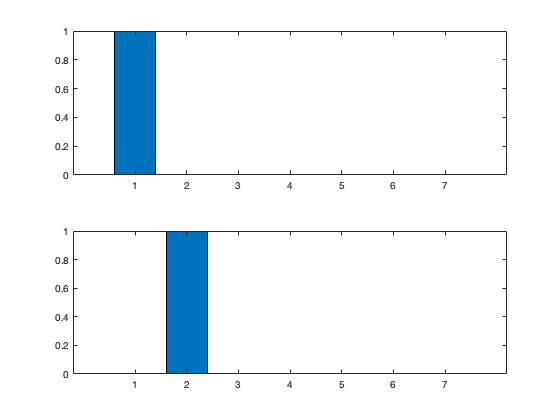

subplot(2,1,1), bar(xi1)
subplot(2,1,2), bar(xi2)

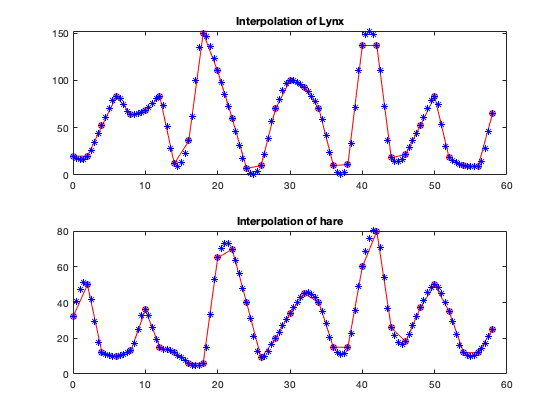



%%%%%% SINDy with interpolation
dt_new = 0.5;
t_new = 0:dt_new:58;
n = length(t_new);


x1_interp = interp1(t,x1,t_new,'makima').';
x2_interp = interp1(t,x2,t_new,'makima').';

fq4 = figure();
subplot(2,1,1)
plot(t,x1,'ro-',t_new,x1_interp,'b*')
title('Interpolation of Lynx')
subplot(2,1,2)
plot(t,x2,'ro-',t_new,x2_interp,'b*')
title('Interpolation of hare')


for j=2:n-1
    x1dot(j-1) = (x1_interp(j+1)-x1_interp(j-1))/(2*dt_new);
    x2dot(j-1) = (x2_interp(j+1)-x2_interp(j-1))/(2*dt_new);
end

x1s = x1_interp(2:n-1);
x2s = x2_interp(2:n-1);
A2 = [x1s x2s x1s.*x2s x1s.^2 x2s.^2 x1s.^2.*x2s x2s.^2.*x1s];
%A2 = [x1s.*x2s x1s.^2 x2s.^2 x1s.^2.*x2s x2s.^2.*x1s];
%xi1=A2\x1dot.';
%xi2=A2\x2dot.';
%xi1=pinv(A2)*x1dot.';
%xi2=pinv(A2)*x2dot.';
xi1=lasso(A2,x1dot.','Lambda',0.001);
xi2=lasso(A2,x2dot.','Lambda',0.001);

fq4_2 = figure()

fq4_2 =   Figure (60) with properties:

      Number: 60
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


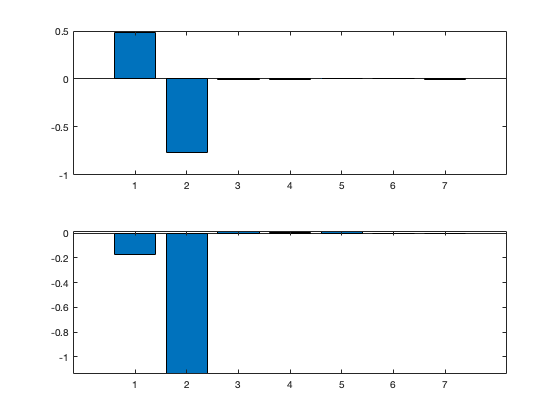

subplot(2,1,1), bar(xi1)
subplot(2,1,2), bar(xi2)